Lös randvärdesproblemet 

${y^{\prime } }^{\prime } \left(x\right)=y\left(x\right)+\frac{2}{3}e^x$, $y\left(0\right)=0$, $y\left(1\right)=\frac{1}{3}e$ med finita differensmetoden och centrala differenser.

Central differens: ${y^{\prime } }^{\prime } \left(x_i \right)\approx \frac{y\left(x_{i+1} \right)-2y\left(x_i \right)+y\left(x_{i-1} \right)}{h^2 }$.

Analytisk lösning är $y\left(x\right)=\frac{{\mathrm{xe}}^x }{3}$.

% Antal delintervall
N=10

N =     10



% Randvillkor
w0=0; 
wN=1/3*exp(1); 

% steglängd h
h=1/N;
% vektor xv (med ränderna inkluderade) 
% och xvint (för inre punkter)
xv=(0:N)'*h;
xvint=(1:N-1)'*h;
% Sätt upp systemmatrisen med eye (enhetsmatris) 
% och diag (diagonalmatris)
% help elmat
A=-(2+h^2)*eye(N-1); 
A=A+diag(ones(N-2,1),-1)+diag(ones(N-2,1),1)

A =   -2.010000000000000   1.000000000000000                   0                   0                   0                   0                   0                   0                   0
   1.000000000000000  -2.010000000000000   1.000000000000000                   0                   0                   0                   0                   0                   0
                   0   1.000000000000000  -2.010000000000000   1.000000000000000                   0                   0                   0                   0                   0
                   0                   0   1.000000000000000  -2.010000000000000   1.000000000000000                   0                   0                   0                   0
                   0                   0                   0   1.000000000000000  -2.010000000000000   1.000000000000000                   0                   0                   0
                   0                   0                   0                   0   1.000000


% Högerledet
b=2/3*h^2*exp(xvint); 
b(1)=b(1)-w0; 
b(end)=b(end)-wN; 

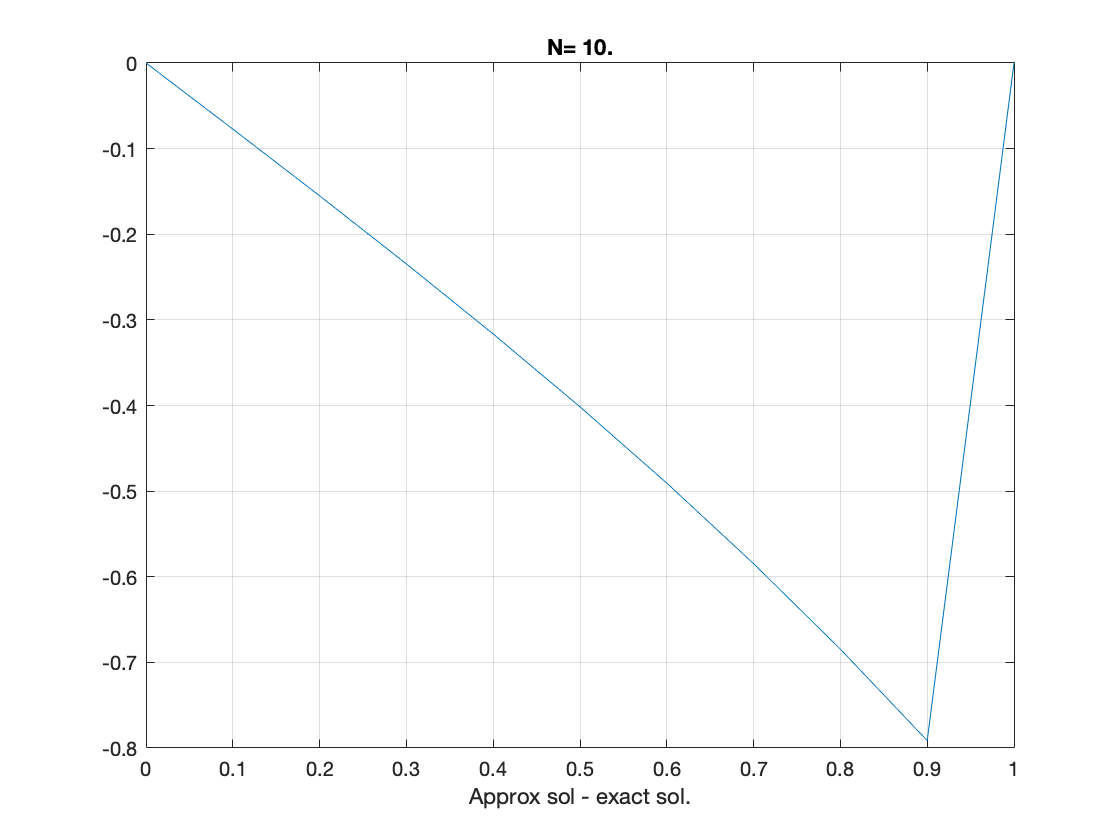


% Lös linjärt ekvationssystem
wsolint=A\b;
% Lägg till randvillkoren
wsol=[w0; wsolint; wN]; 

% analytisk lösning
ysolana=xv.*exp(xv)/3; 

figure
hold off;
plot(xv,wsol-ysolana); 
title(['N= ' num2str(N) '.']);
grid on;
xlabel(['Approx sol - exact sol.']);